# Sleepstudy dataset example

**We'll fit the "sleepstudy" dataset, a standard demo dataset in R, with three different mixed effects models:**

- **fitlme**, Matlab's mixed effects model

- **IGLS**, CANlab's Iterative Generalized Least Squares 2-level model

- **glmfit_multilevel**, CANlab's two-stage reweighted summary statistics model

### Dataset description

#### Description

The average reaction time per day (in milliseconds) for subjects in a sleep deprivation study.

Days 0-1 were adaptation and training (T1/T2), day 2 was baseline (B); sleep deprivation started after day 2.

#### Format

A data frame with 180 observations on the following 3 variables.

**Reaction**: Average reaction time (ms)

**Days**: Number of days of sleep deprivation

**Subject**: Subject number on which the observation was made.

**Details**

These data are from the study described in Belenky et al. (2003), for the most sleep-deprived group (3 hours time-in-bed) and for the first 10 days of the study, up to the recovery period. The original study analyzed speed (1/(reaction time)) and treated day as a categorical rather than a continuous predictor.

**References**

Gregory Belenky, Nancy J. Wesensten, David R. Thorne, Maria L. Thomas, Helen C. Sing, Daniel P. Redmond, Michael B. Russo and Thomas J. Balkin (2003) Patterns of performance degradation and restoration during sleep restriction and subsequent recovery: a sleep dose-response study. Journal of Sleep Research 12, 1--12.

### Load the dataset

Before you start, you'll want the dataset on your path:

sleepstudy = readtable('sleepstudy.csv');

### fitlme

lme = fitlme(sleepstudy,'Reaction ~ Days + (Days | Subject)');
disp(lme)

Linear mixed-effects model fit by ML

Model information:
    Number of observations             180
    Fixed effects coefficients           2
    Random effects coefficients         36
    Covariance parameters                4

Formula:
    Reaction ~ 1 + Days + (1 + Days | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1763.9    1783.1    -875.97          1751.9  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.6323    37.906    178    3.6634e-87    238.32    264.49
    {'Days'       }        10.467      1.5022    6.9678    178    6.0243e-11    7.5028    13.432

Random effects covariance parameters (95% CIs):
Group: Subject (18 Levels)
    Name1                  Name2                  Type            Estimate    Lower

Note: The degrees of freedom and P-values in the fixed effects table are wrong! 

For valid estimates of the dfe, you must correct the df using the Satterthwaite method, or do model comparisons to test significance levels. I prefer the former because it's straightforward.

[~, ~, fixedstats] = fixedEffects(lme, 'DFMethod', 'Satterthwaite');
disp(fixedstats)


    Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                   Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.6323    37.906    18    1.2668e-18    237.47    265.34
    {'Days'       }        10.467      1.5022    6.9678    18    1.6524e-06    7.3112    13.623



The default is maximum likelihood estimation, so let's try it using ReML instead:

lme = fitlme(sleepstudy,'Reaction ~ Days + (Days | Subject)', 'FitMethod','REML');
disp(lme)

Linear mixed-effects model fit by REML

Model information:
    Number of observations             180
    Fixed effects coefficients           2
    Random effects coefficients         36
    Covariance parameters                4

Formula:
    Reaction ~ 1 + Days + (1 + Days | Subject)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1755.6    1774.7    -871.81          1743.6  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.8246    36.838    178    3.3479e-85    237.94    264.87
    {'Days'       }        10.467      1.5458    6.7715    178    1.7872e-10    7.4169    13.518

Random effects covariance parameters (95% CIs):
Group: Subject (18 Levels)
    Name1                  Name2                  Type            Estimate    Low


[~, ~, fixedstats] = fixedEffects(lme, 'DFMethod', 'Satterthwaite');
disp(fixedstats)


    Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                   Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)'}        251.41      6.8246    36.838    17    1.1709e-17    237.01     265.8
    {'Days'       }        10.467      1.5458    6.7715    17    3.2638e-06     7.206    13.729



Let's get the BLUPs, the Best Linear Unbiased Predictors.

- These are estimates of the individual parameters for each person, with shrinkage of high-variance estimates towards the group values. 

- They are deviations around the group (population) values, so we have to add the population parameters to get the individual slopes.

- These are what Doug Bates calls conditional means, E[beta|Y=y], evaluated at the estimated parameters

[~, ~, randomstats] = randomEffects(lme);
blups = reshape(randomstats.Estimate, 2, length(unique(randomstats.Level)))';
levelnames = unique(randomstats.Level);
bnames = unique(randomstats.Name, 'stable')

bnames = 2×1 cell array
    {'(Intercept)'}
    {'Days'       }


blups = array2table(blups, 'Variablenames', bnames, 'RowNames', levelnames )

blups = 18×2 table
           (Intercept)      Days  
           ___________    ________

    308       2.2586         9.199
    309      -40.399       -8.6197
    310       -38.96       -5.4489
    330       23.691       -4.8143
    331        22.26       -3.0699
    332       9.0395      -0.27217
    333        16.84      -0.22362
    334      -7.2326        1.0746
    335      -0.3337       -10.752
    337        34.89        8.6283
    349       -25.21        1.1734
    350       -13.07        6.6142
    351       4.5778       -3.0153
    352       20.864         3.536
    369       3.2755       0.87222
    370      -25.613        4.8225


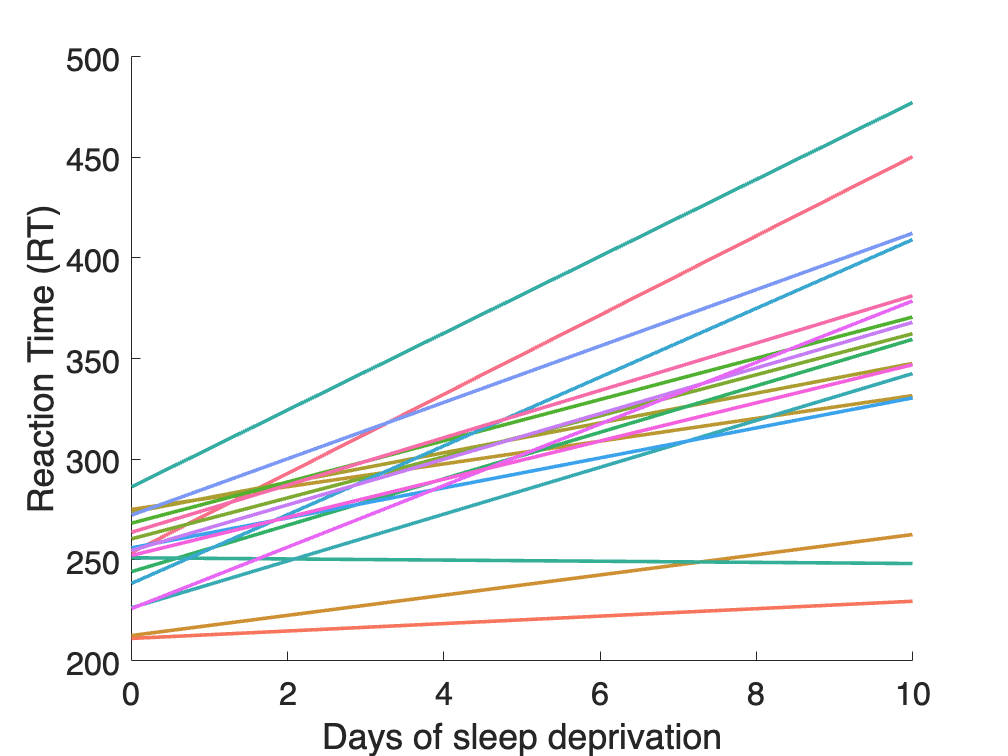


% Now create the plot
% ---------------------------
indiv_slopes = table2array(blups) + lme.Coefficients.Estimate';
days = length(unique(sleepstudy.Days));

% This is a local function created to show a simple plot of slopes
plot_indiv_slopes(indiv_slopes, days);

### IGLS: Iterative generalized least squares

% To use IGLS and glmfit_multilevel, we need to reformat the dataset to
% cell arrays

sleepunstacked = unstack(sleepstudy,'Reaction','Days');

sleepunstacked = table2array(sleepunstacked(:, 2:end))';
[n, m] = size(sleepunstacked);  % n = days, m  = subjects
sleep_rt_cell = mat2cell(sleepunstacked, n, ones(1, m));

daycode = ((1:n)') - 1 ;
X1 = repmat({daycode}, 1, m);


MST (diag of Ystar_mtx): 2251.39771
MSE (diag of resid): -0.00001


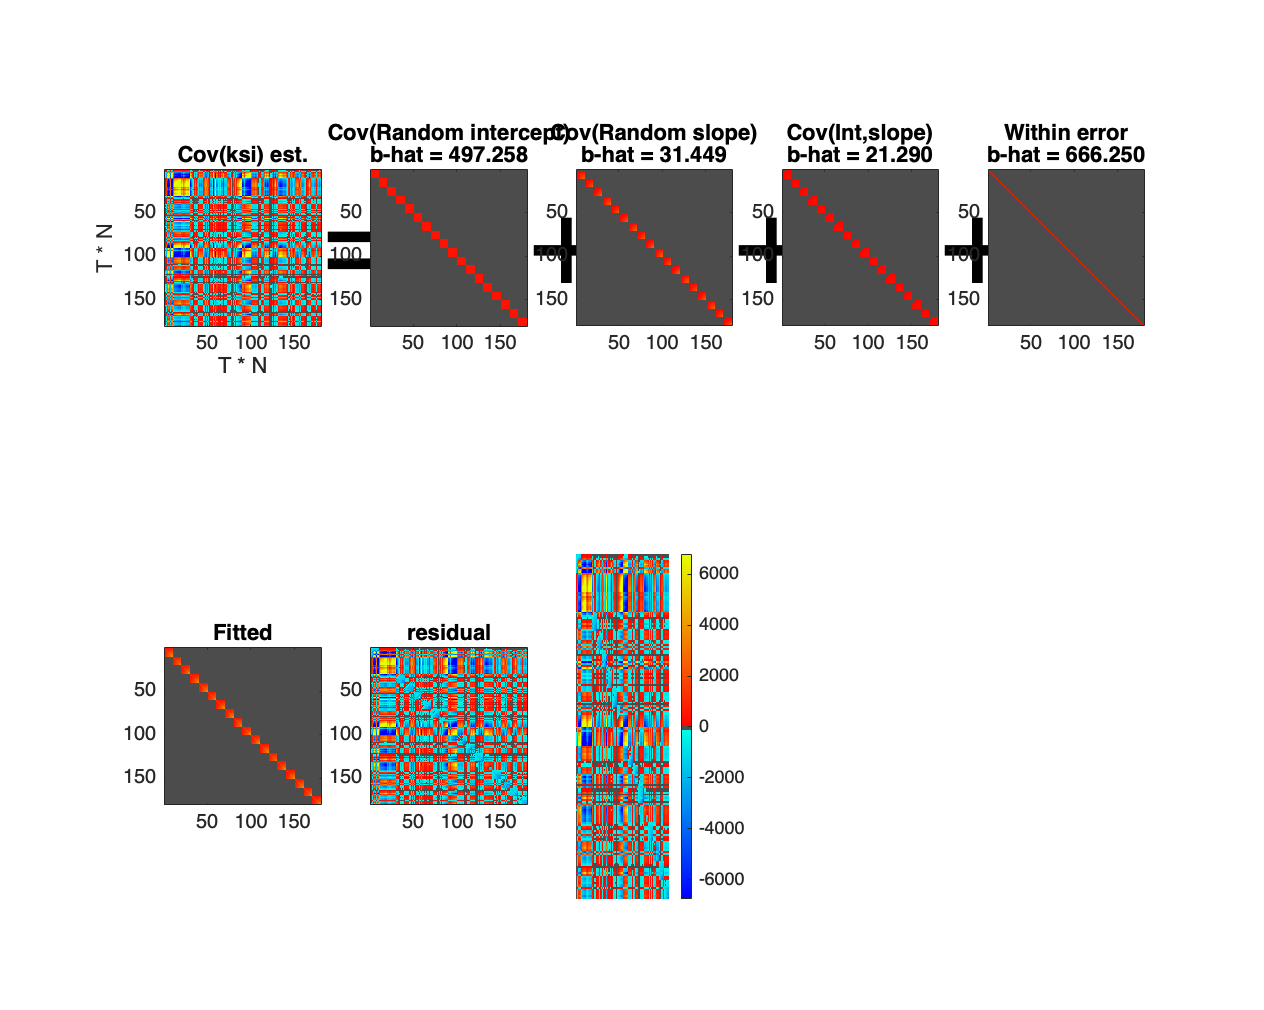

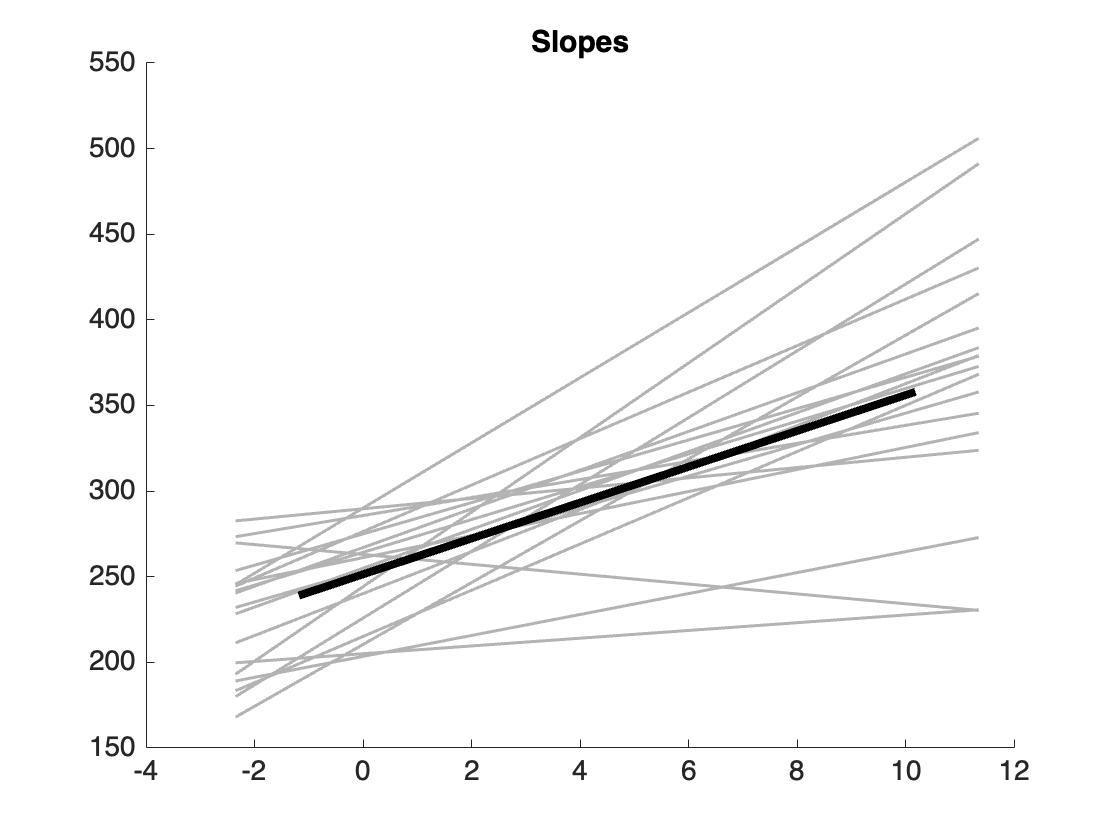


igls.m output report:
---------------------------------------
Data:  10 observations x  18 subjects 
Fit Type: igls
AR(p) model: No
Converged: Yes
Max iterations:   5, Completed iterations:   1
Epsilon for convergence: 0.010000
Elapsed time: 0.29 s

Statistics: Tests of inference on fixed population parameters
Parameter	est.	t( 17)	p	
Intcpt.	251.405	39.55	0.000000	***
Slope1	10.467	7.06	0.000002	***


Statistics: Tests of significance on random effects (variances)
Parameter	est.	LRT	p	
Intcpt.	497.258	22.09	0.000000	***
Slope1	31.449	42.01	0.000000	***

---------------------------------------



% IGLS requires CANlab tools
% see also rigls.m for ReML estimation

igls_stats = igls(sleep_rt_cell, X1, 'plot', 'all');

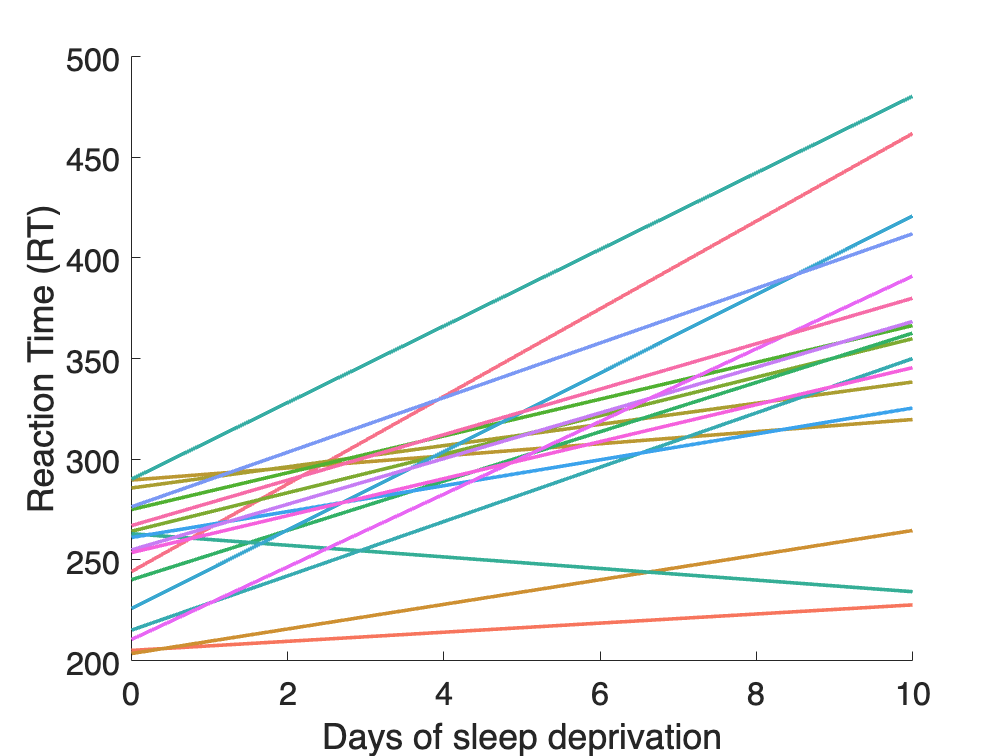

% BLUPs 
% Create the same simple plot as before, to compare
indiv_slopes = igls_stats.beta_indiv';

plot_indiv_slopes(indiv_slopes, days);

Here is a different plot, with different color options.

This plots the naive estimates of individual slopes, not the BLUPs. But you can see that they are very close to the BLUPS in this case.

This requires CANlab tools)

create_figure('example');
handles = line_plot_multisubject(X1, sleep_rt_cell, 'colors', seaborn_colors(length(X1)));

Warnings:

____________________________________________________________________________________________________________________________________________
Y: input cells with low varability:
2
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.54 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, subject is random effect: 
Mean b = 10.47, t( 17) = 6.77, p = 0.

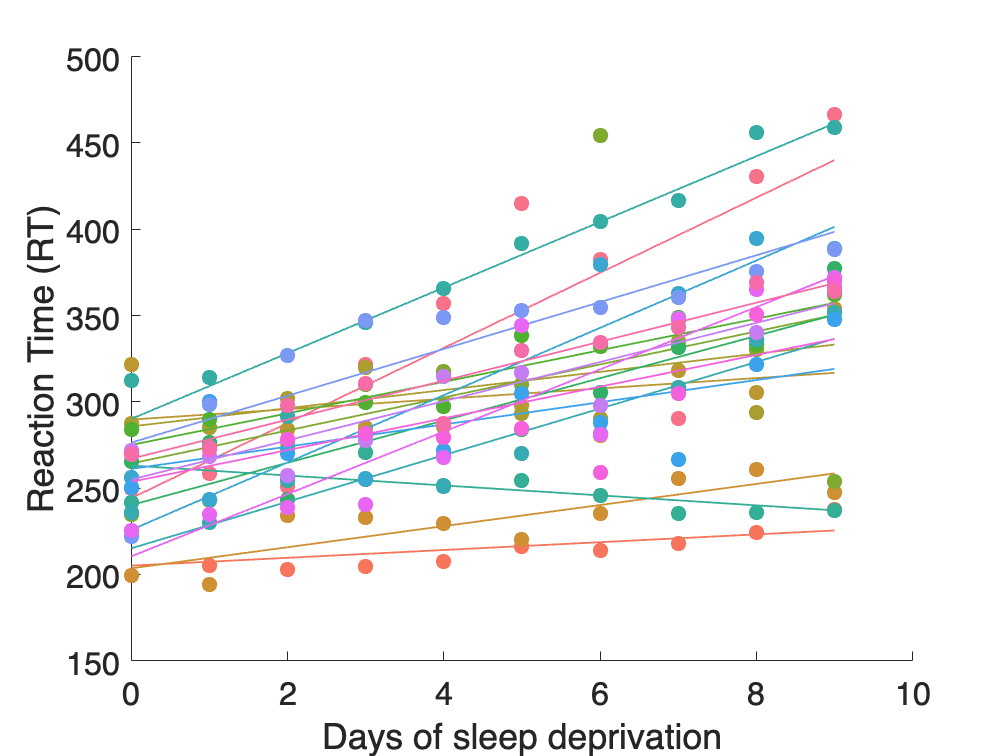

set(handles.point_handles, 'MarkerSize', 8, 'Marker', 'o');
set(gca, 'FontSize', 18);
xlabel('Days of sleep deprivation'); ylabel('Reaction Time (RT)');

### glmfit_multilevel

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  18, Predictors:   1
Outcome names: Intercept	Days	
Weighting option: weighted
Inference option: t-test

Other Options:
	Plots: Yes
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
Total time: 0.04 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	Intercept	Days	
Adj. mean	250.61	10.11	

2nd-level B01
	Intercept	Days	
Coeff	250.61	10.11	
STE	7.14	1.55	
t	35.09	6.53	
Z	8.21	4.54	
p	0.00000	0.00001	

________________________________________


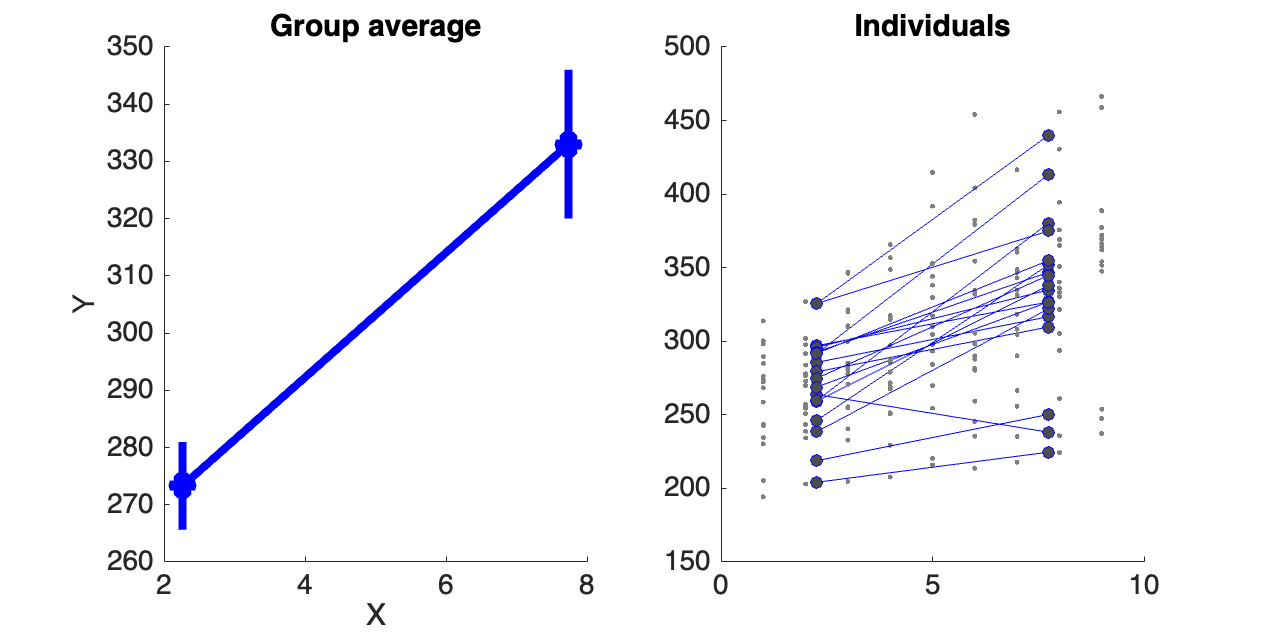

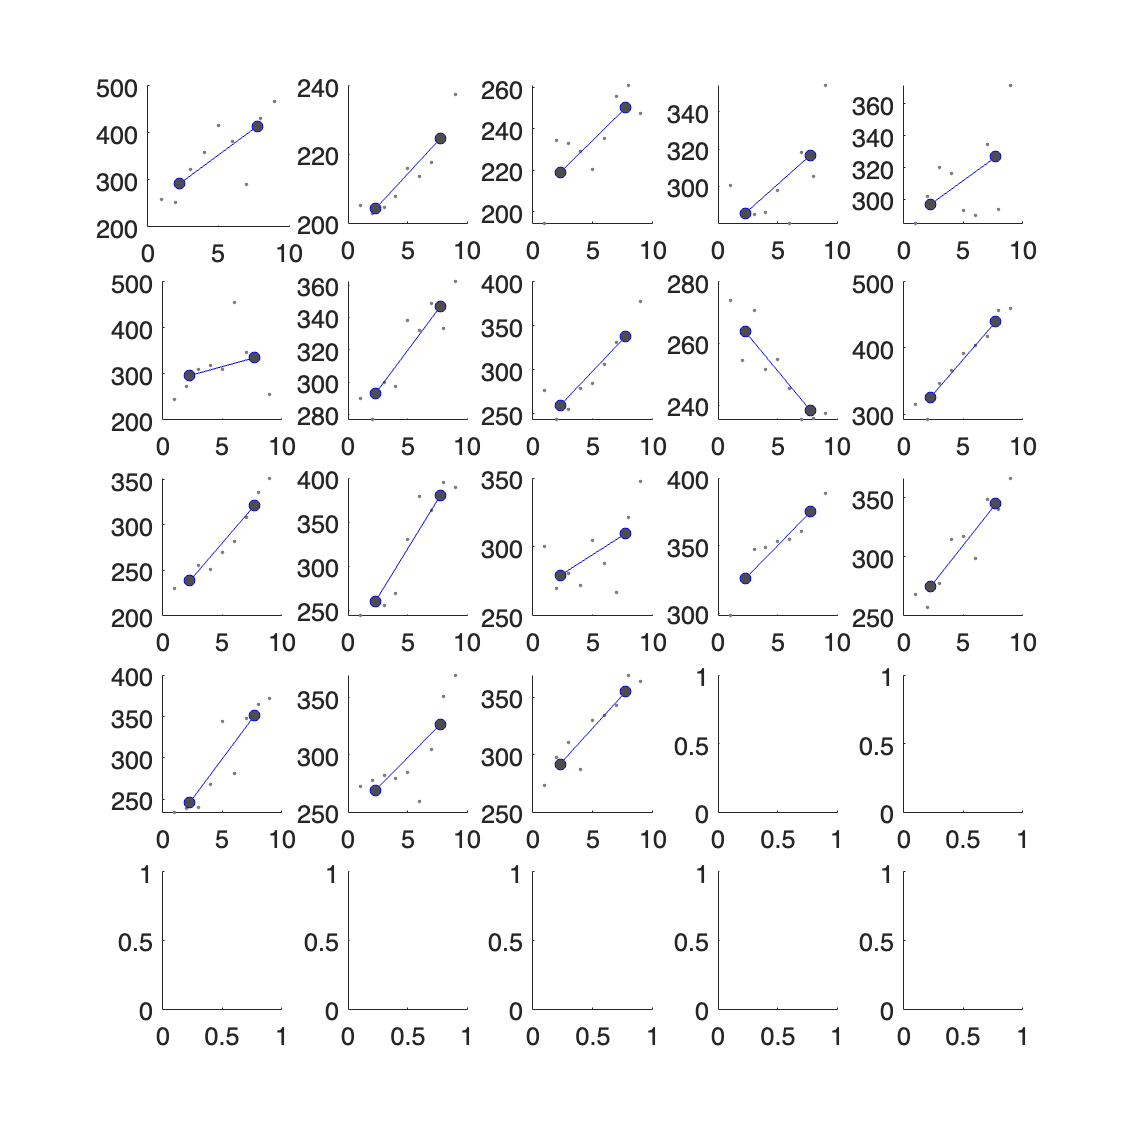

glmfit_stats = glmfit_multilevel(sleep_rt_cell, X1, [], 'names', {'Days'}, 'verbose', 'weighted', 'plot');

function plot_indiv_slopes(indiv_slopes, days)

figure; hold on;
m = size(indiv_slopes, 1); % number of subjects
colors = seaborn_colors(m);

for i = 1:m
    
    % plot individual line
    plot([0 days], [indiv_slopes(i, 1) indiv_slopes(i, 1) + days * indiv_slopes(i, 2)], 'color', colors{i}, 'LineWidth', 2);
    
end

% plot group
% b = lme.Coefficients.Estimate;
% plot([0 days], [b(1) b(1) + days * b(2)], 'color', 'k', 'LineWidth', 4);

set(gca, 'FontSize', 18);
xlabel('Days of sleep deprivation'); ylabel('Reaction Time (RT)');
end